clc
clear
close all
warning off
load InputData\highnetworkdata50.mat  % 1st column is the simulation time
% initial parameters
bufferSize = 100; % packets in buffer
rtt=100e-3; % round trip time in seconds
C  = 10e6/8; % channel capacity in bytes
Pcktsize= 1000; % bytes in a packet

## create DDPG agent & training


env = MyEnviorement_contnus(1,network,bufferSize,Pcktsize,rtt,C);
obsInfo = getObservationInfo(env);
numObservations = obsInfo.Dimension(1);
actInfo = getActionInfo(env);


L=24;
% create a network to be used as underlying critic approximator
statePath = imageInputLayer([obsInfo.Dimension(1) 1 1],'Normalization','none','Name','state');
actionPath = imageInputLayer([actInfo.Dimension(1) 1 1],'Normalization','none','Name','action');
commonPath = [concatenationLayer(1,2,'Name','concat')
             quadraticLayer('Name','quadratic')
             fullyConnectedLayer(1,'Name','StateValue','BiasLearnRateFactor', 0, 'Bias', 0)];
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'state','concat/in1');
criticNetwork = connectLayers(criticNetwork,'action','concat/in2');

% set some options for the critic
criticOpts = rlRepresentationOptions('LearnRate',5e-3,'GradientThreshold',1);

% create the critic based on the network approximator
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation',{'state'},'Action',{'action'},criticOpts);

actorNetwork = [
    imageInputLayer([obsInfo.Dimension(1) 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(actInfo.Dimension(1),'Name','action')];

% set some options for the actor
actorOpts = rlRepresentationOptions('LearnRate',1e-2,'GradientThreshold',1,'UseDevice',"auto");

% create the actor based on the network approximator
actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'state'},'Action',{'action'},actorOpts);

agentOpts = rlDDPGAgentOptions(...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',128);

agent = rlDDPGAgent(actor,critic,agentOpts);
trainOpts = rlTrainingOptions('MaxEpisodes', 500,...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',5000,...
    'Verbose', true, ...
    'SaveAgentDirectory', pwd);
trainingStats = train(agent,env,trainOpts);

Episode:   1/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 3 | Episode Q0 : -0.01


Episode:   2/500 | Episode Reward : -9.98 | Episode Steps:   26 | Avg Reward : -9.99 | Step Count : 29 | Episode Q0 : -0.01


Episode:   3/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 31 | Episode Q0 : -0.01


Episode:   4/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 33 | Episode Q0 : -0.01


Episode:   5/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 34 | Episode Q0 : -0.01


Episode:   6/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 35 | Episode Q0 : -0.01


Episode:   7/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 36 | Episode Q0 : -0.01


Episode:   8/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 37 | Episode Q0 : -0.01


Episode:   9/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 38 | Episode Q0 : -0.01


Episode:  10/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 39 | Episode Q0 : -0.01


Episode:  11/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 44 | Episode Q0 : -0.01


Episode:  12/500 | Episode Reward : -9.97 | Episode Steps:   35 | Avg Reward : -9.99 | Step Count : 79 | Episode Q0 : -0.01


Episode:  13/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -9.99 | Step Count : 83 | Episode Q0 : -0.01


Episode:  14/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 84 | Episode Q0 : -0.01


Episode:  15/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -9.99 | Step Count : 91 | Episode Q0 : -0.01


Episode:  16/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -9.99 | Step Count : 98 | Episode Q0 : -0.01


Episode:  17/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 99 | Episode Q0 : -0.01


Episode:  18/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 100 | Episode Q0 : -0.01


Episode:  19/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -10.00 | Step Count : 106 | Episode Q0 : -0.01


Episode:  20/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 107 | Episode Q0 : -0.01


Episode:  21/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 108 | Episode Q0 : -0.01


Episode:  22/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 109 | Episode Q0 : -0.01


Episode:  23/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 110 | Episode Q0 : -0.01


Episode:  24/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 111 | Episode Q0 : -0.01


Episode:  25/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 113 | Episode Q0 : -0.01


Episode:  26/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 114 | Episode Q0 : -0.01


Episode:  27/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -10.00 | Step Count : 120 | Episode Q0 : -0.01


Episode:  28/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 121 | Episode Q0 : -0.01


Episode:  29/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 122 | Episode Q0 : -0.01


Episode:  30/500 | Episode Reward : -9.98 | Episode Steps:   26 | Avg Reward : -9.99 | Step Count : 148 | Episode Q0 : -0.01


Episode:  31/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -9.99 | Step Count : 153 | Episode Q0 : -0.01


Episode:  32/500 | Episode Reward : -9.99 | Episode Steps:    9 | Avg Reward : -9.99 | Step Count : 162 | Episode Q0 : -0.01


Episode:  33/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 163 | Episode Q0 : -0.01


Episode:  34/500 | Episode Reward : -9.98 | Episode Steps:   17 | Avg Reward : -9.99 | Step Count : 180 | Episode Q0 : -0.01


Episode:  35/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 181 | Episode Q0 : -0.01


Episode:  36/500 | Episode Reward : -28958.44 | Episode Steps:    2 | Avg Reward : -5799.68 | Step Count : 183 | Episode Q0 : -0.01


Episode:  37/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -5799.68 | Step Count : 186 | Episode Q0 : -0.01


Episode:  38/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -5799.68 | Step Count : 187 | Episode Q0 : -0.01


Episode:  39/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -5799.69 | Step Count : 188 | Episode Q0 : -0.01


Episode:  40/500 | Episode Reward : -47174.94 | Episode Steps:    3 | Avg Reward : -15232.67 | Step Count : 191 | Episode Q0 : -0.01


Episode:  41/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9442.99 | Step Count : 192 | Episode Q0 : -0.01


Episode:  42/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9442.99 | Step Count : 193 | Episode Q0 : -0.01


Episode:  43/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9442.99 | Step Count : 194 | Episode Q0 : -0.01


Episode:  44/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9442.99 | Step Count : 195 | Episode Q0 : -0.01


Episode:  45/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -10.00 | Step Count : 202 | Episode Q0 : -0.01


Episode:  46/500 | Episode Reward : -9.91 | Episode Steps:   87 | Avg Reward : -9.98 | Step Count : 289 | Episode Q0 : -0.01


Episode:  47/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.98 | Step Count : 290 | Episode Q0 : -0.01


Episode:  48/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.98 | Step Count : 291 | Episode Q0 : -0.01


Episode:  49/500 | Episode Reward : -25225.31 | Episode Steps:    4 | Avg Reward : -5053.04 | Step Count : 295 | Episode Q0 : -0.01


Episode:  50/500 | Episode Reward : -9.94 | Episode Steps:   59 | Avg Reward : -5053.03 | Step Count : 354 | Episode Q0 : -0.01


Episode:  51/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -5053.05 | Step Count : 358 | Episode Q0 : -0.01


Episode:  52/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -5053.05 | Step Count : 360 | Episode Q0 : -0.01


Episode:  53/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -5053.05 | Step Count : 361 | Episode Q0 : -0.01


Episode:  54/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 362 | Episode Q0 : -0.01


Episode:  55/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 363 | Episode Q0 : -0.01


Episode:  56/500 | Episode Reward : -9.99 | Episode Steps:   14 | Avg Reward : -10.00 | Step Count : 377 | Episode Q0 : -0.01


Episode:  57/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 378 | Episode Q0 : -0.01


Episode:  58/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 379 | Episode Q0 : -0.01


Episode:  59/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 380 | Episode Q0 : -0.01


Episode:  60/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 381 | Episode Q0 : -0.01


Episode:  61/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 383 | Episode Q0 : -0.01


Episode:  62/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 384 | Episode Q0 : -0.02


Episode:  63/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 387 | Episode Q0 : -0.02


Episode:  64/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 388 | Episode Q0 : -0.02


Episode:  65/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 389 | Episode Q0 : -0.02


Episode:  66/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 390 | Episode Q0 : -0.02


Episode:  67/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 392 | Episode Q0 : -0.02


Episode:  68/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 393 | Episode Q0 : -0.02


Episode:  69/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 394 | Episode Q0 : -0.02


Episode:  70/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 395 | Episode Q0 : -0.02


Episode:  71/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 396 | Episode Q0 : -0.02


Episode:  72/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 397 | Episode Q0 : -0.02


Episode:  73/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 398 | Episode Q0 : -0.02


Episode:  74/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 403 | Episode Q0 : -0.02


Episode:  75/500 | Episode Reward : -9.95 | Episode Steps:   51 | Avg Reward : -9.99 | Step Count : 454 | Episode Q0 : -0.02


Episode:  76/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 455 | Episode Q0 : -0.02


Episode:  77/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 456 | Episode Q0 : -0.02


Episode:  78/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 457 | Episode Q0 : -0.02


Episode:  79/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 459 | Episode Q0 : -0.02


Episode:  80/500 | Episode Reward : -9.98 | Episode Steps:   20 | Avg Reward : -10.00 | Step Count : 479 | Episode Q0 : -0.02


Episode:  81/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 480 | Episode Q0 : -0.02


Episode:  82/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 481 | Episode Q0 : -0.02


Episode:  83/500 | Episode Reward : -9.99 | Episode Steps:   13 | Avg Reward : -9.99 | Step Count : 494 | Episode Q0 : -0.02


Episode:  84/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 496 | Episode Q0 : -0.02


Episode:  85/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 497 | Episode Q0 : -0.02


Episode:  86/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 501 | Episode Q0 : -0.02


Episode:  87/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 506 | Episode Q0 : -0.02


Episode:  88/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 508 | Episode Q0 : -0.02


Episode:  89/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 509 | Episode Q0 : -0.02


Episode:  90/500 | Episode Reward : -9.97 | Episode Steps:   27 | Avg Reward : -9.99 | Step Count : 536 | Episode Q0 : -0.02


Episode:  91/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 537 | Episode Q0 : -0.02


Episode:  92/500 | Episode Reward : -7032.12 | Episode Steps:    8 | Avg Reward : -1414.42 | Step Count : 545 | Episode Q0 : -0.02


Episode:  93/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -1414.42 | Step Count : 546 | Episode Q0 : -0.02


Episode:  94/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -1414.42 | Step Count : 547 | Episode Q0 : -0.02


Episode:  95/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -1414.42 | Step Count : 548 | Episode Q0 : -0.02


Episode:  96/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -1414.42 | Step Count : 551 | Episode Q0 : -0.02


Episode:  97/500 | Episode Reward : -9.99 | Episode Steps:   13 | Avg Reward : -10.00 | Step Count : 564 | Episode Q0 : -0.02


Episode:  98/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 565 | Episode Q0 : -0.02


Episode:  99/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 569 | Episode Q0 : -0.02


Episode: 100/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 573 | Episode Q0 : -0.02


Episode: 101/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 574 | Episode Q0 : -0.02


Episode: 102/500 | Episode Reward : -9.99 | Episode Steps:   11 | Avg Reward : -10.00 | Step Count : 585 | Episode Q0 : -0.02


Episode: 103/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 586 | Episode Q0 : -0.02


Episode: 104/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 589 | Episode Q0 : -0.02


Episode: 105/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 591 | Episode Q0 : -0.02


Episode: 106/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 592 | Episode Q0 : -0.02


Episode: 107/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 596 | Episode Q0 : -0.02


Episode: 108/500 | Episode Reward : -2453.14 | Episode Steps:   49 | Avg Reward : -498.63 | Step Count : 645 | Episode Q0 : -0.02


Episode: 109/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -498.63 | Step Count : 646 | Episode Q0 : -0.02


Episode: 110/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -498.63 | Step Count : 647 | Episode Q0 : -0.02


Episode: 111/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -498.63 | Step Count : 648 | Episode Q0 : -0.02


Episode: 112/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -498.63 | Step Count : 649 | Episode Q0 : -0.02


Episode: 113/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 650 | Episode Q0 : -0.02


Episode: 114/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 651 | Episode Q0 : -0.02


Episode: 115/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 656 | Episode Q0 : -0.02


Episode: 116/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 661 | Episode Q0 : -0.02


Episode: 117/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 662 | Episode Q0 : -0.02


Episode: 118/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 663 | Episode Q0 : -0.02


Episode: 119/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 671 | Episode Q0 : -0.02


Episode: 120/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 679 | Episode Q0 : -0.02


Episode: 121/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 687 | Episode Q0 : -0.02


Episode: 122/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 688 | Episode Q0 : -0.02


Episode: 123/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 689 | Episode Q0 : -0.02


Episode: 124/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 692 | Episode Q0 : -0.02


Episode: 125/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 693 | Episode Q0 : -0.02


Episode: 126/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 694 | Episode Q0 : -0.02


Episode: 127/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 695 | Episode Q0 : -0.02


Episode: 128/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 696 | Episode Q0 : -0.02


Episode: 129/500 | Episode Reward : -9.99 | Episode Steps:   14 | Avg Reward : -10.00 | Step Count : 710 | Episode Q0 : -0.02


Episode: 130/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 711 | Episode Q0 : -0.03


Episode: 131/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 712 | Episode Q0 : -0.03


Episode: 132/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 713 | Episode Q0 : -0.03


Episode: 133/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 714 | Episode Q0 : -0.03


Episode: 134/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 715 | Episode Q0 : -0.03


Episode: 135/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 716 | Episode Q0 : -0.03


Episode: 136/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 717 | Episode Q0 : -0.03


Episode: 137/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 718 | Episode Q0 : -0.03


Episode: 138/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 719 | Episode Q0 : -0.03


Episode: 139/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 720 | Episode Q0 : -0.03


Episode: 140/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 721 | Episode Q0 : -0.03


Episode: 141/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 722 | Episode Q0 : -0.03


Episode: 142/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 723 | Episode Q0 : -0.03


Episode: 143/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 724 | Episode Q0 : -0.03


Episode: 144/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 725 | Episode Q0 : -0.03


Episode: 145/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 726 | Episode Q0 : -0.03


Episode: 146/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 727 | Episode Q0 : -0.03


Episode: 147/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 731 | Episode Q0 : -0.03


Episode: 148/500 | Episode Reward : -9.97 | Episode Steps:   32 | Avg Reward : -9.99 | Step Count : 763 | Episode Q0 : -0.03


Episode: 149/500 | Episode Reward : -9.99 | Episode Steps:   15 | Avg Reward : -9.99 | Step Count : 778 | Episode Q0 : -0.03


Episode: 150/500 | Episode Reward : -9.97 | Episode Steps:   28 | Avg Reward : -9.98 | Step Count : 806 | Episode Q0 : -0.03


Episode: 151/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -9.98 | Step Count : 810 | Episode Q0 : -0.03


Episode: 152/500 | Episode Reward : -9.99 | Episode Steps:   11 | Avg Reward : -9.98 | Step Count : 821 | Episode Q0 : -0.03


Episode: 153/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 822 | Episode Q0 : -0.03


Episode: 154/500 | Episode Reward : -9.95 | Episode Steps:   46 | Avg Reward : -9.98 | Step Count : 868 | Episode Q0 : -0.03


Episode: 155/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 869 | Episode Q0 : -0.03


Episode: 156/500 | Episode Reward : -22402.85 | Episode Steps:   24 | Avg Reward : -4488.56 | Step Count : 893 | Episode Q0 : -0.03


Episode: 157/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -4488.56 | Step Count : 894 | Episode Q0 : -0.03


Episode: 158/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -4488.56 | Step Count : 895 | Episode Q0 : -0.03


Episode: 159/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -4488.57 | Step Count : 900 | Episode Q0 : -0.03


Episode: 160/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -4488.57 | Step Count : 901 | Episode Q0 : -0.03


Episode: 161/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 902 | Episode Q0 : -0.03


Episode: 162/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 903 | Episode Q0 : -0.03


Episode: 163/500 | Episode Reward : -9.98 | Episode Steps:   24 | Avg Reward : -9.99 | Step Count : 927 | Episode Q0 : -0.03


Episode: 164/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 930 | Episode Q0 : -0.03


Episode: 165/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -9.99 | Step Count : 936 | Episode Q0 : -0.03


Episode: 166/500 | Episode Reward : -49548.81 | Episode Steps:    5 | Avg Reward : -9917.76 | Step Count : 941 | Episode Q0 : -0.03


Episode: 167/500 | Episode Reward : -9.98 | Episode Steps:   24 | Avg Reward : -9917.75 | Step Count : 965 | Episode Q0 : -0.03


Episode: 168/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9917.76 | Step Count : 966 | Episode Q0 : -0.03


Episode: 169/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9917.76 | Step Count : 967 | Episode Q0 : -0.03


Episode: 170/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9917.76 | Step Count : 968 | Episode Q0 : -0.03


Episode: 171/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 969 | Episode Q0 : -0.03


Episode: 172/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 971 | Episode Q0 : -0.03


Episode: 173/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 976 | Episode Q0 : -0.03


Episode: 174/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 977 | Episode Q0 : -0.03


Episode: 175/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 978 | Episode Q0 : -0.03


Episode: 176/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 979 | Episode Q0 : -0.03


Episode: 177/500 | Episode Reward : -9.99 | Episode Steps:   12 | Avg Reward : -10.00 | Step Count : 991 | Episode Q0 : -0.03


Episode: 178/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 992 | Episode Q0 : -0.03


Episode: 179/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 993 | Episode Q0 : -0.03


Episode: 180/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 994 | Episode Q0 : -0.03


Episode: 181/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 995 | Episode Q0 : -0.03


Episode: 182/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 996 | Episode Q0 : -0.03


Episode: 183/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 997 | Episode Q0 : -0.03


Episode: 184/500 | Episode Reward : -48261.75 | Episode Steps:    7 | Avg Reward : -9660.35 | Step Count : 1004 | Episode Q0 : -0.03


Episode: 185/500 | Episode Reward : -9.96 | Episode Steps:   43 | Avg Reward : -9660.34 | Step Count : 1047 | Episode Q0 : -0.03


Episode: 186/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -9660.34 | Step Count : 1051 | Episode Q0 : -0.04


Episode: 187/500 | Episode Reward : -14387.18 | Episode Steps:    8 | Avg Reward : -12535.78 | Step Count : 1059 | Episode Q0 : -0.04


Episode: 188/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -12535.78 | Step Count : 1060 | Episode Q0 : -0.04


Episode: 189/500 | Episode Reward : -9.99 | Episode Steps:   14 | Avg Reward : -2885.42 | Step Count : 1074 | Episode Q0 : -0.04


Episode: 190/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -2885.43 | Step Count : 1080 | Episode Q0 : -0.04


Episode: 191/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -2885.43 | Step Count : 1084 | Episode Q0 : -0.04


Episode: 192/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1086 | Episode Q0 : -0.04


Episode: 193/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1087 | Episode Q0 : -0.04


Episode: 194/500 | Episode Reward : -9.99 | Episode Steps:   10 | Avg Reward : -10.00 | Step Count : 1097 | Episode Q0 : -0.04


Episode: 195/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1098 | Episode Q0 : -0.04


Episode: 196/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1101 | Episode Q0 : -0.04


Episode: 197/500 | Episode Reward : -9.99 | Episode Steps:   11 | Avg Reward : -10.00 | Step Count : 1112 | Episode Q0 : -0.04


Episode: 198/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1113 | Episode Q0 : -0.04


Episode: 199/500 | Episode Reward : -18481.75 | Episode Steps:    3 | Avg Reward : -3704.35 | Step Count : 1116 | Episode Q0 : -0.04


Episode: 200/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -3704.35 | Step Count : 1117 | Episode Q0 : -0.04


Episode: 201/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -3704.35 | Step Count : 1118 | Episode Q0 : -0.04


Episode: 202/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -3704.35 | Step Count : 1119 | Episode Q0 : -0.04


Episode: 203/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -3704.35 | Step Count : 1120 | Episode Q0 : -0.04


Episode: 204/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1121 | Episode Q0 : -0.04


Episode: 205/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1122 | Episode Q0 : -0.04


Episode: 206/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1123 | Episode Q0 : -0.04


Episode: 207/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1124 | Episode Q0 : -0.04


Episode: 208/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1125 | Episode Q0 : -0.04


Episode: 209/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1126 | Episode Q0 : -0.04


Episode: 210/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1127 | Episode Q0 : -0.04


Episode: 211/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1128 | Episode Q0 : -0.04


Episode: 212/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1129 | Episode Q0 : -0.04


Episode: 213/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1130 | Episode Q0 : -0.04


Episode: 214/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1131 | Episode Q0 : -0.04


Episode: 215/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1132 | Episode Q0 : -0.04


Episode: 216/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1133 | Episode Q0 : -0.04


Episode: 217/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1134 | Episode Q0 : -0.04


Episode: 218/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1135 | Episode Q0 : -0.04


Episode: 219/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1138 | Episode Q0 : -0.04


Episode: 220/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1140 | Episode Q0 : -0.04


Episode: 221/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1142 | Episode Q0 : -0.04


Episode: 222/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 1147 | Episode Q0 : -0.04


Episode: 223/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1148 | Episode Q0 : -0.04


Episode: 224/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1149 | Episode Q0 : -0.04


Episode: 225/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1150 | Episode Q0 : -0.04


Episode: 226/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1151 | Episode Q0 : -0.04


Episode: 227/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -10.00 | Step Count : 1167 | Episode Q0 : -0.04


Episode: 228/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -10.00 | Step Count : 1174 | Episode Q0 : -0.04


Episode: 229/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1177 | Episode Q0 : -0.04


Episode: 230/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1180 | Episode Q0 : -0.04


Episode: 231/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1181 | Episode Q0 : -0.04


Episode: 232/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1182 | Episode Q0 : -0.04


Episode: 233/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 1187 | Episode Q0 : -0.04


Episode: 234/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1188 | Episode Q0 : -0.04


Episode: 235/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1191 | Episode Q0 : -0.04


Episode: 236/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -10.00 | Step Count : 1207 | Episode Q0 : -0.04


Episode: 237/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -9.99 | Step Count : 1215 | Episode Q0 : -0.04


Episode: 238/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1216 | Episode Q0 : -0.04


Episode: 239/500 | Episode Reward : -9.99 | Episode Steps:    9 | Avg Reward : -9.99 | Step Count : 1225 | Episode Q0 : -0.04


Episode: 240/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 1227 | Episode Q0 : -0.04


Episode: 241/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1228 | Episode Q0 : -0.04


Episode: 242/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1229 | Episode Q0 : -0.04


Episode: 243/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1230 | Episode Q0 : -0.04


Episode: 244/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1231 | Episode Q0 : -0.04


Episode: 245/500 | Episode Reward : -9.99 | Episode Steps:   12 | Avg Reward : -10.00 | Step Count : 1243 | Episode Q0 : -0.04


Episode: 246/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1244 | Episode Q0 : -0.04


Episode: 247/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1245 | Episode Q0 : -0.04


Episode: 248/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1246 | Episode Q0 : -0.04


Episode: 249/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1249 | Episode Q0 : -0.04


Episode: 250/500 | Episode Reward : -4109.31 | Episode Steps:    2 | Avg Reward : -829.86 | Step Count : 1251 | Episode Q0 : -0.04


Episode: 251/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -829.86 | Step Count : 1267 | Episode Q0 : -0.04


Episode: 252/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -829.86 | Step Count : 1268 | Episode Q0 : -0.04


Episode: 253/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -829.86 | Step Count : 1269 | Episode Q0 : -0.04


Episode: 254/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -829.86 | Step Count : 1270 | Episode Q0 : -0.04


Episode: 255/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1271 | Episode Q0 : -0.04


Episode: 256/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1272 | Episode Q0 : -0.04


Episode: 257/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1273 | Episode Q0 : -0.04


Episode: 258/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1274 | Episode Q0 : -0.04


Episode: 259/500 | Episode Reward : -9.98 | Episode Steps:   23 | Avg Reward : -10.00 | Step Count : 1297 | Episode Q0 : -0.04


Episode: 260/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1298 | Episode Q0 : -0.04


Episode: 261/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1299 | Episode Q0 : -0.04


Episode: 262/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 1302 | Episode Q0 : -0.04


Episode: 263/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1304 | Episode Q0 : -0.04


Episode: 264/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1305 | Episode Q0 : -0.04


Episode: 265/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1306 | Episode Q0 : -0.04


Episode: 266/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1307 | Episode Q0 : -0.04


Episode: 267/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1308 | Episode Q0 : -0.04


Episode: 268/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1310 | Episode Q0 : -0.04


Episode: 269/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1311 | Episode Q0 : -0.04


Episode: 270/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1312 | Episode Q0 : -0.04


Episode: 271/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1313 | Episode Q0 : -0.04


Episode: 272/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1314 | Episode Q0 : -0.04


Episode: 273/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1315 | Episode Q0 : -0.04


Episode: 274/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 1323 | Episode Q0 : -0.04


Episode: 275/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1324 | Episode Q0 : -0.04


Episode: 276/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1325 | Episode Q0 : -0.04


Episode: 277/500 | Episode Reward : -9.99 | Episode Steps:   13 | Avg Reward : -10.00 | Step Count : 1338 | Episode Q0 : -0.04


Episode: 278/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1340 | Episode Q0 : -0.04


Episode: 279/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1341 | Episode Q0 : -0.04


Episode: 280/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1342 | Episode Q0 : -0.04


Episode: 281/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 1346 | Episode Q0 : -0.04


Episode: 282/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1347 | Episode Q0 : -0.04


Episode: 283/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1348 | Episode Q0 : -0.04


Episode: 284/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1349 | Episode Q0 : -0.04


Episode: 285/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1350 | Episode Q0 : -0.04


Episode: 286/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1351 | Episode Q0 : -0.04


Episode: 287/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1352 | Episode Q0 : -0.04


Episode: 288/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1353 | Episode Q0 : -0.04


Episode: 289/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1354 | Episode Q0 : -0.04


Episode: 290/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1355 | Episode Q0 : -0.04


Episode: 291/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1356 | Episode Q0 : -0.04


Episode: 292/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1357 | Episode Q0 : -0.04


Episode: 293/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 1365 | Episode Q0 : -0.04


Episode: 294/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1366 | Episode Q0 : -0.04


Episode: 295/500 | Episode Reward : -9.99 | Episode Steps:   13 | Avg Reward : -10.00 | Step Count : 1379 | Episode Q0 : -0.04


Episode: 296/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1381 | Episode Q0 : -0.04


Episode: 297/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1382 | Episode Q0 : -0.04


Episode: 298/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1384 | Episode Q0 : -0.04


Episode: 299/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1385 | Episode Q0 : -0.04


Episode: 300/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1386 | Episode Q0 : -0.04


Episode: 301/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1387 | Episode Q0 : -0.04


Episode: 302/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1388 | Episode Q0 : -0.04


Episode: 303/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1389 | Episode Q0 : -0.04


Episode: 304/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1390 | Episode Q0 : -0.04


Episode: 305/500 | Episode Reward : -19187.55 | Episode Steps:    9 | Avg Reward : -3845.51 | Step Count : 1399 | Episode Q0 : -0.04


Episode: 306/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -3845.51 | Step Count : 1401 | Episode Q0 : -0.04


Episode: 307/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -3845.51 | Step Count : 1405 | Episode Q0 : -0.04


Episode: 308/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -3845.51 | Step Count : 1407 | Episode Q0 : -0.04


Episode: 309/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -3845.51 | Step Count : 1409 | Episode Q0 : -0.04


Episode: 310/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -10.00 | Step Count : 1425 | Episode Q0 : -0.04


Episode: 311/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1426 | Episode Q0 : -0.05


Episode: 312/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -9.99 | Step Count : 1442 | Episode Q0 : -0.05


Episode: 313/500 | Episode Reward : -9.99 | Episode Steps:   15 | Avg Reward : -9.99 | Step Count : 1457 | Episode Q0 : -0.05


Episode: 314/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1458 | Episode Q0 : -0.05


Episode: 315/500 | Episode Reward : -9.98 | Episode Steps:   19 | Avg Reward : -9.99 | Step Count : 1477 | Episode Q0 : -0.05


Episode: 316/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1478 | Episode Q0 : -0.05


Episode: 317/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1479 | Episode Q0 : -0.05


Episode: 318/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1480 | Episode Q0 : -0.05


Episode: 319/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1481 | Episode Q0 : -0.05


Episode: 320/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1482 | Episode Q0 : -0.05


Episode: 321/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1483 | Episode Q0 : -0.05


Episode: 322/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1484 | Episode Q0 : -0.05


Episode: 323/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1485 | Episode Q0 : -0.05


Episode: 324/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 1489 | Episode Q0 : -0.05


Episode: 325/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1490 | Episode Q0 : -0.05


Episode: 326/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1491 | Episode Q0 : -0.05


Episode: 327/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1492 | Episode Q0 : -0.05


Episode: 328/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1493 | Episode Q0 : -0.05


Episode: 329/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1494 | Episode Q0 : -0.05


Episode: 330/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1495 | Episode Q0 : -0.05


Episode: 331/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1496 | Episode Q0 : -0.05


Episode: 332/500 | Episode Reward : -9.97 | Episode Steps:   27 | Avg Reward : -9.99 | Step Count : 1523 | Episode Q0 : -0.05


Episode: 333/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -9.99 | Step Count : 1526 | Episode Q0 : -0.05


Episode: 334/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1527 | Episode Q0 : -0.05


Episode: 335/500 | Episode Reward : -54062.38 | Episode Steps:    6 | Avg Reward : -10820.47 | Step Count : 1533 | Episode Q0 : -0.05


Episode: 336/500 | Episode Reward : -9.98 | Episode Steps:   18 | Avg Reward : -10820.47 | Step Count : 1551 | Episode Q0 : -0.05


Episode: 337/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10820.47 | Step Count : 1552 | Episode Q0 : -0.05


Episode: 338/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10820.47 | Step Count : 1553 | Episode Q0 : -0.05


Episode: 339/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -10820.47 | Step Count : 1559 | Episode Q0 : -0.05


Episode: 340/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1560 | Episode Q0 : -0.05


Episode: 341/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1561 | Episode Q0 : -0.05


Episode: 342/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1562 | Episode Q0 : -0.05


Episode: 343/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1563 | Episode Q0 : -0.05


Episode: 344/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1565 | Episode Q0 : -0.05


Episode: 345/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1566 | Episode Q0 : -0.05


Episode: 346/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1567 | Episode Q0 : -0.05


Episode: 347/500 | Episode Reward : -39747.24 | Episode Steps:   14 | Avg Reward : -7957.45 | Step Count : 1581 | Episode Q0 : -0.05


Episode: 348/500 | Episode Reward : -9.97 | Episode Steps:   28 | Avg Reward : -7957.44 | Step Count : 1609 | Episode Q0 : -0.05


Episode: 349/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -7957.44 | Step Count : 1612 | Episode Q0 : -0.05


Episode: 350/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -7957.44 | Step Count : 1614 | Episode Q0 : -0.05


Episode: 351/500 | Episode Reward : -9.96 | Episode Steps:   41 | Avg Reward : -7957.43 | Step Count : 1655 | Episode Q0 : -0.05


Episode: 352/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1656 | Episode Q0 : -0.05


Episode: 353/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1657 | Episode Q0 : -0.05


Episode: 354/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1658 | Episode Q0 : -0.05


Episode: 355/500 | Episode Reward : -9.95 | Episode Steps:   47 | Avg Reward : -9.98 | Step Count : 1705 | Episode Q0 : -0.05


Episode: 356/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1706 | Episode Q0 : -0.05


Episode: 357/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1707 | Episode Q0 : -0.05


Episode: 358/500 | Episode Reward : -10158.00 | Episode Steps:   64 | Avg Reward : -2039.59 | Step Count : 1771 | Episode Q0 : -0.05


Episode: 359/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -2039.59 | Step Count : 1778 | Episode Q0 : -0.05


Episode: 360/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -2039.60 | Step Count : 1784 | Episode Q0 : -0.05


Episode: 361/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -2039.60 | Step Count : 1785 | Episode Q0 : -0.05


Episode: 362/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -2039.60 | Step Count : 1786 | Episode Q0 : -0.05


Episode: 363/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1787 | Episode Q0 : -0.05


Episode: 364/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1788 | Episode Q0 : -0.05


Episode: 365/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1789 | Episode Q0 : -0.05


Episode: 366/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1790 | Episode Q0 : -0.05


Episode: 367/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1791 | Episode Q0 : -0.05


Episode: 368/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1792 | Episode Q0 : -0.05


Episode: 369/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1793 | Episode Q0 : -0.05


Episode: 370/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1794 | Episode Q0 : -0.05


Episode: 371/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1795 | Episode Q0 : -0.05


Episode: 372/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1796 | Episode Q0 : -0.05


Episode: 373/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1797 | Episode Q0 : -0.05


Episode: 374/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1798 | Episode Q0 : -0.05


Episode: 375/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1799 | Episode Q0 : -0.05


Episode: 376/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1800 | Episode Q0 : -0.05


Episode: 377/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1801 | Episode Q0 : -0.05


Episode: 378/500 | Episode Reward : -9.99 | Episode Steps:   10 | Avg Reward : -10.00 | Step Count : 1811 | Episode Q0 : -0.05


Episode: 379/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1812 | Episode Q0 : -0.05


Episode: 380/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1813 | Episode Q0 : -0.05


Episode: 381/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1814 | Episode Q0 : -0.05


Episode: 382/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1815 | Episode Q0 : -0.05


Episode: 383/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1816 | Episode Q0 : -0.05


Episode: 384/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1817 | Episode Q0 : -0.05


Episode: 385/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1818 | Episode Q0 : -0.05


Episode: 386/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1819 | Episode Q0 : -0.05


Episode: 387/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1820 | Episode Q0 : -0.05


Episode: 388/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1821 | Episode Q0 : -0.05


Episode: 389/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 1829 | Episode Q0 : -0.05


Episode: 390/500 | Episode Reward : -31946.99 | Episode Steps:    5 | Avg Reward : -6397.40 | Step Count : 1834 | Episode Q0 : -0.05


Episode: 391/500 | Episode Reward : -39600.56 | Episode Steps:    3 | Avg Reward : -14315.51 | Step Count : 1837 | Episode Q0 : -0.06


Episode: 392/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -14315.51 | Step Count : 1838 | Episode Q0 : -0.06


Episode: 393/500 | Episode Reward : -8173.92 | Episode Steps:   16 | Avg Reward : -15948.29 | Step Count : 1854 | Episode Q0 : -0.06


Episode: 394/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -15948.29 | Step Count : 1855 | Episode Q0 : -0.06


Episode: 395/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9560.90 | Step Count : 1856 | Episode Q0 : -0.06


Episode: 396/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -1642.78 | Step Count : 1857 | Episode Q0 : -0.06


Episode: 397/500 | Episode Reward : -9.99 | Episode Steps:   10 | Avg Reward : -1642.78 | Step Count : 1867 | Episode Q0 : -0.06


Episode: 398/500 | Episode Reward : -9.98 | Episode Steps:   17 | Avg Reward : -10.00 | Step Count : 1884 | Episode Q0 : -0.06


Episode: 399/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 1886 | Episode Q0 : -0.06


Episode: 400/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 1888 | Episode Q0 : -0.06


Episode: 401/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1889 | Episode Q0 : -0.06


Episode: 402/500 | Episode Reward : -9.98 | Episode Steps:   16 | Avg Reward : -9.99 | Step Count : 1905 | Episode Q0 : -0.06


Episode: 403/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1906 | Episode Q0 : -0.06


Episode: 404/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1907 | Episode Q0 : -0.06


Episode: 405/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1908 | Episode Q0 : -0.06


Episode: 406/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1909 | Episode Q0 : -0.06


Episode: 407/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1911 | Episode Q0 : -0.06


Episode: 408/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 1916 | Episode Q0 : -0.06


Episode: 409/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 1918 | Episode Q0 : -0.06


Episode: 410/500 | Episode Reward : -9.98 | Episode Steps:   19 | Avg Reward : -10.00 | Step Count : 1937 | Episode Q0 : -0.06


Episode: 411/500 | Episode Reward : -9.99 | Episode Steps:   10 | Avg Reward : -9.99 | Step Count : 1947 | Episode Q0 : -0.06


Episode: 412/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1948 | Episode Q0 : -0.06


Episode: 413/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1949 | Episode Q0 : -0.06


Episode: 414/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1950 | Episode Q0 : -0.06


Episode: 415/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1951 | Episode Q0 : -0.06


Episode: 416/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1952 | Episode Q0 : -0.06


Episode: 417/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1953 | Episode Q0 : -0.06


Episode: 418/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 1954 | Episode Q0 : -0.06


Episode: 419/500 | Episode Reward : -9.97 | Episode Steps:   36 | Avg Reward : -9.99 | Step Count : 1990 | Episode Q0 : -0.06


Episode: 420/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1991 | Episode Q0 : -0.06


Episode: 421/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -9.99 | Step Count : 1996 | Episode Q0 : -0.06


Episode: 422/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 1997 | Episode Q0 : -0.06


Episode: 423/500 | Episode Reward : -9.99 | Episode Steps:   14 | Avg Reward : -9.99 | Step Count : 2011 | Episode Q0 : -0.06


Episode: 424/500 | Episode Reward : -10.00 | Episode Steps:    4 | Avg Reward : -10.00 | Step Count : 2015 | Episode Q0 : -0.06


Episode: 425/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2016 | Episode Q0 : -0.06


Episode: 426/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2017 | Episode Q0 : -0.06


Episode: 427/500 | Episode Reward : -9.99 | Episode Steps:    8 | Avg Reward : -10.00 | Step Count : 2025 | Episode Q0 : -0.06


Episode: 428/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2026 | Episode Q0 : -0.06


Episode: 429/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 2028 | Episode Q0 : -0.06


Episode: 430/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2029 | Episode Q0 : -0.06


Episode: 431/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 2031 | Episode Q0 : -0.06


Episode: 432/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -10.00 | Step Count : 2036 | Episode Q0 : -0.06


Episode: 433/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 2039 | Episode Q0 : -0.06


Episode: 434/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2040 | Episode Q0 : -0.06


Episode: 435/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2041 | Episode Q0 : -0.06


Episode: 436/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2042 | Episode Q0 : -0.06


Episode: 437/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2043 | Episode Q0 : -0.06


Episode: 438/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2044 | Episode Q0 : -0.06


Episode: 439/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2045 | Episode Q0 : -0.06


Episode: 440/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2046 | Episode Q0 : -0.06


Episode: 441/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2047 | Episode Q0 : -0.06


Episode: 442/500 | Episode Reward : -21517.56 | Episode Steps:    4 | Avg Reward : -4311.51 | Step Count : 2051 | Episode Q0 : -0.06


Episode: 443/500 | Episode Reward : -47467.63 | Episode Steps:   20 | Avg Reward : -13803.04 | Step Count : 2071 | Episode Q0 : -0.06


Episode: 444/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -13803.04 | Step Count : 2072 | Episode Q0 : -0.06


Episode: 445/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -13803.04 | Step Count : 2073 | Episode Q0 : -0.06


Episode: 446/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -13803.04 | Step Count : 2074 | Episode Q0 : -0.06


Episode: 447/500 | Episode Reward : -43908.74 | Episode Steps:   12 | Avg Reward : -18281.27 | Step Count : 2086 | Episode Q0 : -0.06


Episode: 448/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -8789.75 | Step Count : 2088 | Episode Q0 : -0.06


Episode: 449/500 | Episode Reward : -9.97 | Episode Steps:   30 | Avg Reward : -8789.74 | Step Count : 2118 | Episode Q0 : -0.06


Episode: 450/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -8789.74 | Step Count : 2124 | Episode Q0 : -0.06


Episode: 451/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -8789.74 | Step Count : 2125 | Episode Q0 : -0.06


Episode: 452/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -9.99 | Step Count : 2127 | Episode Q0 : -0.06


Episode: 453/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 2128 | Episode Q0 : -0.06


Episode: 454/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2129 | Episode Q0 : -0.06


Episode: 455/500 | Episode Reward : -9.99 | Episode Steps:    9 | Avg Reward : -10.00 | Step Count : 2138 | Episode Q0 : -0.06


Episode: 456/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2139 | Episode Q0 : -0.06


Episode: 457/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2140 | Episode Q0 : -0.06


Episode: 458/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2141 | Episode Q0 : -0.06


Episode: 459/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2142 | Episode Q0 : -0.06


Episode: 460/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2143 | Episode Q0 : -0.06


Episode: 461/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2144 | Episode Q0 : -0.06


Episode: 462/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2145 | Episode Q0 : -0.06


Episode: 463/500 | Episode Reward : -10.00 | Episode Steps:    3 | Avg Reward : -10.00 | Step Count : 2148 | Episode Q0 : -0.06


Episode: 464/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2149 | Episode Q0 : -0.06


Episode: 465/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2150 | Episode Q0 : -0.06


Episode: 466/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2151 | Episode Q0 : -0.06


Episode: 467/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2152 | Episode Q0 : -0.06


Episode: 468/500 | Episode Reward : -9.99 | Episode Steps:   10 | Avg Reward : -10.00 | Step Count : 2162 | Episode Q0 : -0.06


Episode: 469/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2163 | Episode Q0 : -0.06


Episode: 470/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2164 | Episode Q0 : -0.06


Episode: 471/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2165 | Episode Q0 : -0.06


Episode: 472/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2166 | Episode Q0 : -0.06


Episode: 473/500 | Episode Reward : -10.00 | Episode Steps:    2 | Avg Reward : -10.00 | Step Count : 2168 | Episode Q0 : -0.06


Episode: 474/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2169 | Episode Q0 : -0.06


Episode: 475/500 | Episode Reward : -9.99 | Episode Steps:    7 | Avg Reward : -10.00 | Step Count : 2176 | Episode Q0 : -0.06


Episode: 476/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2177 | Episode Q0 : -0.06


Episode: 477/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2178 | Episode Q0 : -0.06


Episode: 478/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2179 | Episode Q0 : -0.06


Episode: 479/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2180 | Episode Q0 : -0.06


Episode: 480/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2181 | Episode Q0 : -0.06


Episode: 481/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2182 | Episode Q0 : -0.06


Episode: 482/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2183 | Episode Q0 : -0.06


Episode: 483/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2184 | Episode Q0 : -0.06


Episode: 484/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2185 | Episode Q0 : -0.06


Episode: 485/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2186 | Episode Q0 : -0.06


Episode: 486/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2187 | Episode Q0 : -0.06


Episode: 487/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2188 | Episode Q0 : -0.06


Episode: 488/500 | Episode Reward : -9.99 | Episode Steps:    6 | Avg Reward : -10.00 | Step Count : 2194 | Episode Q0 : -0.06


Episode: 489/500 | Episode Reward : -9.96 | Episode Steps:   38 | Avg Reward : -9.99 | Step Count : 2232 | Episode Q0 : -0.06


Episode: 490/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 2233 | Episode Q0 : -0.06


Episode: 491/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 2234 | Episode Q0 : -0.06


Episode: 492/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -9.99 | Step Count : 2235 | Episode Q0 : -0.06


Episode: 493/500 | Episode Reward : -10.00 | Episode Steps:    5 | Avg Reward : -9.99 | Step Count : 2240 | Episode Q0 : -0.06


Episode: 494/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2241 | Episode Q0 : -0.06


Episode: 495/500 | Episode Reward : -40898.13 | Episode Steps:    4 | Avg Reward : -8187.62 | Step Count : 2245 | Episode Q0 : -0.06


Episode: 496/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -8187.62 | Step Count : 2246 | Episode Q0 : -0.06


Episode: 497/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -8187.62 | Step Count : 2247 | Episode Q0 : -0.06


Episode: 498/500 | Episode Reward : -9.99 | Episode Steps:   15 | Avg Reward : -8187.62 | Step Count : 2262 | Episode Q0 : -0.06


Episode: 499/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -8187.62 | Step Count : 2263 | Episode Q0 : -0.06


Episode: 500/500 | Episode Reward : -10.00 | Episode Steps:    1 | Avg Reward : -10.00 | Step Count : 2264 | Episode Q0 : -0.07


save(trainOpts.SaveAgentDirectory + "/finalAgentDDPG.mat",'agent')
simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

figure
plot(criticNetwork)
title('DDPG network for training')
saveimage_publish(['Results/','/','DDPG training network'])


## create DQN agent

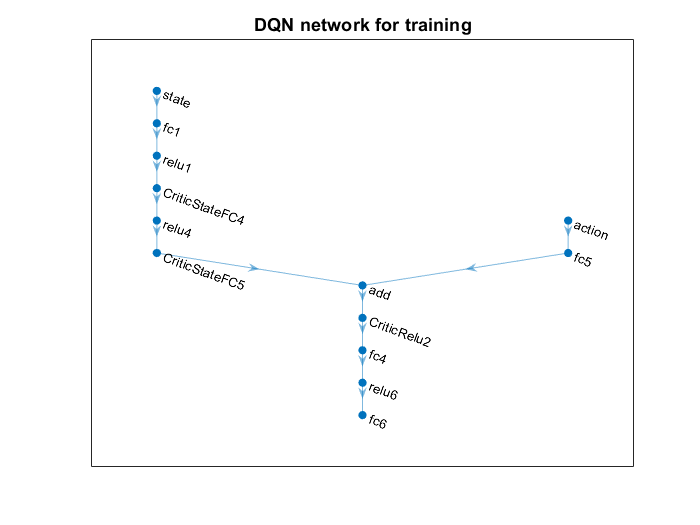

env_dqn = MyEnviorement_discrte(1,network,bufferSize,Pcktsize,rtt,C);

obsInfo_dqn = getObservationInfo(env_dqn);
numObservations = obsInfo_dqn.Dimension(1);
actInfo_dqn = getActionInfo(env_dqn);

numDiscreteAct = actInfo_dqn.Dimension(1);
% criticNetwork = [
%     sequenceInputLayer(numObservations,'Normalization','none','Name','state')
%     fullyConnectedLayer(24, 'Name', 'CriticStateFC1')
%     reluLayer('Name','CriticRelu1')
%     lstmLayer(100,'OutputMode','sequence','Name','CriticLSTM');
%     fullyConnectedLayer(100,'Name','CriticStateFC2')
%     reluLayer('Name','CriticRelu2')
%     fullyConnectedLayer(numDiscreteAct,'Name','action')];

%    imageInputLayer([numObservations 1 1],'Normalization','none','Name','state')

L = 100; % number of neurons
statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(L,'Name','fc1')
    reluLayer('Name','relu1')
%     fullyConnectedLayer(100,'Name','CriticStateFC2')
%     reluLayer('Name','relu2')
%     fullyConnectedLayer(200,'Name','CriticStateFC3')
%     reluLayer('Name','relu3')
    fullyConnectedLayer(L/2,'Name','CriticStateFC4')
    reluLayer('Name','relu4')
    fullyConnectedLayer(ceil(L/3),'Name','CriticStateFC5')
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticRelu2')
    fullyConnectedLayer(L/4,'Name','fc4')
    reluLayer('Name','relu6')
    fullyConnectedLayer(1,'Name','fc6')];
% 
actionPath = [
    imageInputLayer([numDiscreteAct 1 1],'Normalization','none','Name','action')
    
    fullyConnectedLayer(ceil(L/3),'Name','fc5')];
    
% 
criticNetwork_DQN = layerGraph(statePath);
criticNetwork_DQN = addLayers(criticNetwork_DQN, actionPath);    
criticNetwork_DQN = connectLayers(criticNetwork_DQN,'fc5','add/in2');
figure
plot(criticNetwork_DQN)
title('DQN network for training')
saveimage_publish(['Results/','/','DQN training network'])

criticOpts = rlRepresentationOptions('LearnRate',0.001,'GradientThreshold',1,'UseDevice',"auto");
critic = rlQValueRepresentation(criticNetwork,obsInfo_dqn,actInfo_dqn,'Observation',{'state'},'Action',{'action'},criticOpts);
agentOpts = rlDQNAgentOptions(...
    'SampleTime',10,...
    'UseDoubleDQN',false,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',0.99,...
    'ExperienceBufferLength',1e6,...
    'MiniBatchSize',128);
% agentOpts = rlDQNAgentOptions;
% agentOpts = rlDQNAgentOptions('SequenceLength',10);
agent = rlDQNAgent(critic,agentOpts);
trainOpts = rlTrainingOptions('MaxEpisodes', 500,...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',100,...
    'Verbose', true, ...
    'SaveAgentDirectory', pwd);
trainingStats = train(agent,env_dqn,trainOpts);

Episode:   1/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 500 | Episode Q0 : 0.00


Episode:   2/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 1000 | Episode Q0 : 0.00


Episode:   3/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 1500 | Episode Q0 : 0.00


Episode:   4/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 2000 | Episode Q0 : 0.01


Episode:   5/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 2500 | Episode Q0 : 0.01


Episode:   6/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 3000 | Episode Q0 : 0.01


Episode:   7/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 3500 | Episode Q0 : 0.01


Episode:   8/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 4000 | Episode Q0 : 0.01


Episode:   9/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 4500 | Episode Q0 : 0.01


Episode:  10/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 5000 | Episode Q0 : 0.01


save(trainOpts.SaveAgentDirectory + "/finalAgentDQN.mat",'agent')
simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

## create rlTD3 agent & training

env_rlTD3 = MyEnviorement_contnus(1,network,bufferSize,Pcktsize,rtt,C);
obsInfo_rlTD3 = getObservationInfo(env_rlTD3);
numObservations = obsInfo_rlTD3.Dimension(1);
actInfo_rlTD3 = getActionInfo(env_rlTD3);


L=24;
% create a network to be used as underlying critic approximator
statePath = imageInputLayer([obsInfo_rlTD3.Dimension(1) 1 1],'Normalization','none','Name','state');
actionPath = imageInputLayer([actInfo_rlTD3.Dimension(1) 1 1],'Normalization','none','Name','action');
commonPath = [concatenationLayer(1,2,'Name','concat')
             quadraticLayer('Name','quadratic')
             fullyConnectedLayer(1,'Name','StateValue','BiasLearnRateFactor', 0, 'Bias', 0)];
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'state','concat/in1');
criticNetwork = connectLayers(criticNetwork,'action','concat/in2');

% set some options for the critic
criticOpts = rlRepresentationOptions('LearnRate',5e-3,'GradientThreshold',1);

% create the critic based on the network approximator
critic = rlQValueRepresentation(criticNetwork,obsInfo_rlTD3,actInfo_rlTD3,...
    'Observation',{'state'},'Action',{'action'},criticOpts);

actorNetwork = [
    imageInputLayer([obsInfo_rlTD3.Dimension(1) 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(actInfo_rlTD3.Dimension(1),'Name','action')];

% set some options for the actor
actorOpts = rlRepresentationOptions('LearnRate',1e-2,'GradientThreshold',1,'UseDevice',"auto");

% create the actor based on the network approximator
actor =  rlDeterministicActorRepresentation(actorNetwork,obsInfo_rlTD3,actInfo_rlTD3,...
    'Observation',{'state'},'Action',{'action'},actorOpts);

agentOpts =  rlTD3AgentOptions(...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',128);

agent = rlTD3Agent(actor,critic,agentOpts);
trainOpts = rlTrainingOptions('MaxEpisodes', 500,...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',5000,...
    'Verbose', true, ...
    'SaveAgentDirectory', pwd);
trainingStats = train(agent,env_rlTD3,trainOpts);
save(trainOpts.SaveAgentDirectory + "/finalAgentrlTD3.mat",'agent')
simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

## PPO Training


env_PPO = MyEnviorement_discrte(1,network,bufferSize,Pcktsize,rtt,C);

obsInfo_PPO = getObservationInfo(env_PPO);
numObservations = obsInfo_PPO.Dimension(1);
actInfo_PPO = getActionInfo(env_PPO);

numDiscreteAct = actInfo_PPO.Dimension(1);

% L = 100; % number of neurons
% statePath = [
%     imageInputLayer([numObservations 1 1],'Normalization','none','Name','state')
%     fullyConnectedLayer(L,'Name','fc1')
%     reluLayer('Name','relu1')
%     fullyConnectedLayer(L/2,'Name','CriticStateFC4')
%     reluLayer('Name','relu4')
%     fullyConnectedLayer(ceil(L/3),'Name','CriticStateFC5')
%     additionLayer(2,'Name','add')
%     reluLayer('Name','CriticRelu2')
%     fullyConnectedLayer(L/4,'Name','fc4')
%     reluLayer('Name','relu6')
%     fullyConnectedLayer(1,'Name','fc6')];
% % 
% actionPath = [
%     imageInputLayer([numDiscreteAct 1 1],'Normalization','none','Name','action')
%     
%     fullyConnectedLayer(ceil(L/3),'Name','fc5')];
%     
% % 
% criticNetwork_PPO = layerGraph(statePath);
% criticNetwork_PPO = addLayers(criticNetwork_PPO, actionPath);    
% criticNetwork_PPO = connectLayers(criticNetwork_PPO,'fc5','add/in2');

% criticNetwork_PPO = [
%     imageInputLayer([numObservations 1 1],'Normalization','none','Name','state')
%     fullyConnectedLayer(1,'Name','CriticFC')];

criticNetwork_PPO = [
    sequenceInputLayer(numObservations,'Normalization','none','Name','state')
    fullyConnectedLayer(8, 'Name', 'fc')
    reluLayer('Name','relu')
    lstmLayer(8,'OutputMode','sequence','Name','lstm')
    fullyConnectedLayer(1,'Name','output')];


criticOpts = rlRepresentationOptions('LearnRate',0.001,'GradientThreshold',1,'UseDevice','gpu');
critic = rlValueRepresentation(criticNetwork_PPO,obsInfo_PPO,'Observation',{'state'},criticOpts);

% actorNetwork = [
%     imageInputLayer([obsInfo_PPO.Dimension(1) 1 1],'Normalization','none','Name','state')
%     fullyConnectedLayer(actInfo_PPO.Dimension(1),'Name','action')];
% actorNetwork = [
%     sequenceInputLayer(obsInfo_PPO.Dimension(1),'Normalization','none','Name','state')
%     fullyConnectedLayer(8,'Name','fc')
%     reluLayer('Name','relu')
%     lstmLayer(8,'OutputMode','sequence','Name','lstm')
%     fullyConnectedLayer(2*numDiscreteAct,'Name','output')
%     softmaxLayer('Name','actionProb')];

actorNetwork = [
    sequenceInputLayer(obsInfo_PPO.Dimension(1),'Normalization','none','Name','state')
    fullyConnectedLayer(8,'Name','fc')
    reluLayer('Name','relu')
    lstmLayer(8,'OutputMode','sequence','Name','lstm')
    fullyConnectedLayer(2*numDiscreteAct,'Name','output')
    softmaxLayer('Name','actionProb')];
% set some options for the actor
actorOpts = rlRepresentationOptions('LearnRate',1e-2,'GradientThreshold',1,'UseDevice',"gpu");

% create the actor based on the network approximator
actor =  rlStochasticActorRepresentation(actorNetwork,obsInfo_PPO,actInfo_PPO,...
    'Observation',{'state'},actorOpts);
agentOpts = rlPPOAgentOptions;

agent = rlPPOAgent(actor,critic,agentOpts);
trainOpts = rlTrainingOptions('MaxEpisodes', 500,...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',100,...
    'Verbose', true, ...
    'SaveAgentDirectory', pwd);
trainingStats = train(agent,env_PPO,trainOpts);

Episode:   1/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 500 | Episode Q0 : 0.00


Episode:   2/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 1000 | Episode Q0 : 0.01


Episode:   3/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 1500 | Episode Q0 : 0.02


Episode:   4/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 2000 | Episode Q0 : 0.02


Episode:   5/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 2500 | Episode Q0 : 0.03


Episode:   6/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 3000 | Episode Q0 : 0.03


Episode:   7/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 3500 | Episode Q0 : 0.04


Episode:   8/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 4000 | Episode Q0 : 0.04


Episode:   9/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 4500 | Episode Q0 : 0.04


Episode:  10/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 5000 | Episode Q0 : 0.04


Episode:  11/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 5500 | Episode Q0 : 0.05


Episode:  12/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 6000 | Episode Q0 : 0.05


Episode:  13/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 6500 | Episode Q0 : 0.05


Episode:  14/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 7000 | Episode Q0 : 0.05


Episode:  15/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 7500 | Episode Q0 : 0.06


Episode:  16/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 8000 | Episode Q0 : 0.06


Episode:  17/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 8500 | Episode Q0 : 0.06


Episode:  18/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 9000 | Episode Q0 : 0.06


Episode:  19/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 9500 | Episode Q0 : 0.06


Episode:  20/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 10000 | Episode Q0 : 0.06


Episode:  21/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 10500 | Episode Q0 : 0.06


Episode:  22/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 11000 | Episode Q0 : 0.07


Episode:  23/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 11500 | Episode Q0 : 0.07


Episode:  24/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 12000 | Episode Q0 : 0.07


Episode:  25/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 12500 | Episode Q0 : 0.07


Episode:  26/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 13000 | Episode Q0 : 0.07


Episode:  27/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 13500 | Episode Q0 : 0.07


Episode:  28/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 14000 | Episode Q0 : 0.07


Episode:  29/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 14500 | Episode Q0 : 0.07


Episode:  30/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 15000 | Episode Q0 : 0.07


Episode:  31/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 15500 | Episode Q0 : 0.07


Episode:  32/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 16000 | Episode Q0 : 0.07


Episode:  33/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 16500 | Episode Q0 : 0.08


Episode:  34/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 17000 | Episode Q0 : 0.08


Episode:  35/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 17500 | Episode Q0 : 0.08


Episode:  36/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 18000 | Episode Q0 : 0.08


Episode:  37/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 18500 | Episode Q0 : 0.08


Episode:  38/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 19000 | Episode Q0 : 0.08


Episode:  39/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 19500 | Episode Q0 : 0.08


Episode:  40/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 20000 | Episode Q0 : 0.08


Episode:  41/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 20500 | Episode Q0 : 0.08


Episode:  42/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 21000 | Episode Q0 : 0.08


Episode:  43/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 21500 | Episode Q0 : 0.08


Episode:  44/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 22000 | Episode Q0 : 0.08


Episode:  45/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 22500 | Episode Q0 : 0.08


Episode:  46/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 23000 | Episode Q0 : 0.08


Episode:  47/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 23500 | Episode Q0 : 0.08


Episode:  48/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 24000 | Episode Q0 : 0.08


Episode:  49/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 24500 | Episode Q0 : 0.08


Episode:  50/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 25000 | Episode Q0 : 0.08


Episode:  51/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 25500 | Episode Q0 : 0.08


Episode:  52/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 26000 | Episode Q0 : 0.08


Episode:  53/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 26500 | Episode Q0 : 0.08


Episode:  54/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 27000 | Episode Q0 : 0.08


Episode:  55/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 27500 | Episode Q0 : 0.08


Episode:  56/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 28000 | Episode Q0 : 0.08


Episode:  57/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 28500 | Episode Q0 : 0.08


Episode:  58/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 29000 | Episode Q0 : 0.08


Episode:  59/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 29500 | Episode Q0 : 0.08


Episode:  60/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 30000 | Episode Q0 : 0.09


Episode:  61/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 30500 | Episode Q0 : 0.09


Episode:  62/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 31000 | Episode Q0 : 0.09


Episode:  63/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 31500 | Episode Q0 : 0.09


Episode:  64/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 32000 | Episode Q0 : 0.09


Episode:  65/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 32500 | Episode Q0 : 0.09


Episode:  66/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 33000 | Episode Q0 : 0.09


Episode:  67/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 33500 | Episode Q0 : 0.09


Episode:  68/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 34000 | Episode Q0 : 0.09


Episode:  69/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 34500 | Episode Q0 : 0.09


Episode:  70/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 35000 | Episode Q0 : 0.09


Episode:  71/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 35500 | Episode Q0 : 0.09


Episode:  72/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 36000 | Episode Q0 : 0.09


Episode:  73/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 36500 | Episode Q0 : 0.09


Episode:  74/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 37000 | Episode Q0 : 0.09


Episode:  75/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 37500 | Episode Q0 : 0.09


Episode:  76/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 38000 | Episode Q0 : 0.09


Episode:  77/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 38500 | Episode Q0 : 0.09


Episode:  78/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 39000 | Episode Q0 : 0.09


Episode:  79/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 39500 | Episode Q0 : 0.09


Episode:  80/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 40000 | Episode Q0 : 0.09


Episode:  81/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 40500 | Episode Q0 : 0.09


Episode:  82/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 41000 | Episode Q0 : 0.09


Episode:  83/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 41500 | Episode Q0 : 0.09


Episode:  84/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 42000 | Episode Q0 : 0.09


Episode:  85/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 42500 | Episode Q0 : 0.09


Episode:  86/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 43000 | Episode Q0 : 0.09


Episode:  87/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 43500 | Episode Q0 : 0.09


Episode:  88/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 44000 | Episode Q0 : 0.09


Episode:  89/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 44500 | Episode Q0 : 0.09


Episode:  90/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 45000 | Episode Q0 : 0.09


Episode:  91/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 45500 | Episode Q0 : 0.09


Episode:  92/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 46000 | Episode Q0 : 0.09


Episode:  93/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 46500 | Episode Q0 : 0.09


Episode:  94/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 47000 | Episode Q0 : 0.09


Episode:  95/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 47500 | Episode Q0 : 0.09


Episode:  96/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 48000 | Episode Q0 : 0.09


Episode:  97/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 48500 | Episode Q0 : 0.09


Episode:  98/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 49000 | Episode Q0 : 0.09


Episode:  99/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 49500 | Episode Q0 : 0.09


Episode: 100/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 50000 | Episode Q0 : 0.09


Episode: 101/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 50500 | Episode Q0 : 0.09


Episode: 102/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 51000 | Episode Q0 : 0.09


Episode: 103/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 51500 | Episode Q0 : 0.09


Episode: 104/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 52000 | Episode Q0 : 0.09


Episode: 105/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 52500 | Episode Q0 : 0.09


Episode: 106/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 53000 | Episode Q0 : 0.09


Episode: 107/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 53500 | Episode Q0 : 0.09


Episode: 108/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 54000 | Episode Q0 : 0.09


Episode: 109/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 54500 | Episode Q0 : 0.09


Episode: 110/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 55000 | Episode Q0 : 0.09


Episode: 111/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 55500 | Episode Q0 : 0.09


Episode: 112/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 56000 | Episode Q0 : 0.09


Episode: 113/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 56500 | Episode Q0 : 0.09


Episode: 114/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 57000 | Episode Q0 : 0.09


Episode: 115/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 57500 | Episode Q0 : 0.09


Episode: 116/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 58000 | Episode Q0 : 0.09


Episode: 117/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 58500 | Episode Q0 : 0.09


Episode: 118/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 59000 | Episode Q0 : 0.09


Episode: 119/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 59500 | Episode Q0 : 0.09


Episode: 120/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 60000 | Episode Q0 : 0.09


Episode: 121/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 60500 | Episode Q0 : 0.09


Episode: 122/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 61000 | Episode Q0 : 0.09


Episode: 123/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 61500 | Episode Q0 : 0.09


Episode: 124/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 62000 | Episode Q0 : 0.09


Episode: 125/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 62500 | Episode Q0 : 0.09


Episode: 126/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 63000 | Episode Q0 : 0.09


Episode: 127/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 63500 | Episode Q0 : 0.10


Episode: 128/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 64000 | Episode Q0 : 0.10


Episode: 129/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 64500 | Episode Q0 : 0.10


Episode: 130/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 65000 | Episode Q0 : 0.10


Episode: 131/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 65500 | Episode Q0 : 0.10


Episode: 132/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 66000 | Episode Q0 : 0.10


Episode: 133/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 66500 | Episode Q0 : 0.10


Episode: 134/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 67000 | Episode Q0 : 0.10


Episode: 135/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 67500 | Episode Q0 : 0.10


Episode: 136/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 68000 | Episode Q0 : 0.10


Episode: 137/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 68500 | Episode Q0 : 0.10


Episode: 138/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 69000 | Episode Q0 : 0.10


Episode: 139/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 69500 | Episode Q0 : 0.10


Episode: 140/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 70000 | Episode Q0 : 0.10


Episode: 141/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 70500 | Episode Q0 : 0.10


Episode: 142/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 71000 | Episode Q0 : 0.10


Episode: 143/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 71500 | Episode Q0 : 0.10


Episode: 144/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 72000 | Episode Q0 : 0.10


Episode: 145/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 72500 | Episode Q0 : 0.10


Episode: 146/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 73000 | Episode Q0 : 0.10


Episode: 147/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 73500 | Episode Q0 : 0.10


Episode: 148/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 74000 | Episode Q0 : 0.10


Episode: 149/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 74500 | Episode Q0 : 0.10


Episode: 150/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 75000 | Episode Q0 : 0.10


Episode: 151/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 75500 | Episode Q0 : 0.10


Episode: 152/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 76000 | Episode Q0 : 0.10


Episode: 153/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 76500 | Episode Q0 : 0.10


Episode: 154/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 77000 | Episode Q0 : 0.10


Episode: 155/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 77500 | Episode Q0 : 0.10


Episode: 156/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 78000 | Episode Q0 : 0.10


Episode: 157/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 78500 | Episode Q0 : 0.10


Episode: 158/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 79000 | Episode Q0 : 0.10


Episode: 159/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 79500 | Episode Q0 : 0.10


Episode: 160/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 80000 | Episode Q0 : 0.10


Episode: 161/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 80500 | Episode Q0 : 0.10


Episode: 162/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 81000 | Episode Q0 : 0.10


Episode: 163/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 81500 | Episode Q0 : 0.10


Episode: 164/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 82000 | Episode Q0 : 0.10


Episode: 165/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 82500 | Episode Q0 : 0.10


Episode: 166/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 83000 | Episode Q0 : 0.10


Episode: 167/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 83500 | Episode Q0 : 0.10


Episode: 168/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 84000 | Episode Q0 : 0.10


Episode: 169/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 84500 | Episode Q0 : 0.10


Episode: 170/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 85000 | Episode Q0 : 0.10


Episode: 171/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 85500 | Episode Q0 : 0.10


Episode: 172/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 86000 | Episode Q0 : 0.10


Episode: 173/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 86500 | Episode Q0 : 0.10


Episode: 174/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 87000 | Episode Q0 : 0.10


Episode: 175/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 87500 | Episode Q0 : 0.10


Episode: 176/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 88000 | Episode Q0 : 0.10


Episode: 177/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 88500 | Episode Q0 : 0.10


Episode: 178/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 89000 | Episode Q0 : 0.10


Episode: 179/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 89500 | Episode Q0 : 0.10


Episode: 180/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 90000 | Episode Q0 : 0.10


Episode: 181/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 90500 | Episode Q0 : 0.10


Episode: 182/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 91000 | Episode Q0 : 0.10


Episode: 183/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 91500 | Episode Q0 : 0.10


Episode: 184/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 92000 | Episode Q0 : 0.10


Episode: 185/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 92500 | Episode Q0 : 0.10


Episode: 186/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 93000 | Episode Q0 : 0.10


Episode: 187/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 93500 | Episode Q0 : 0.10


Episode: 188/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 94000 | Episode Q0 : 0.10


Episode: 189/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 94500 | Episode Q0 : 0.10


Episode: 190/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 95000 | Episode Q0 : 0.10


Episode: 191/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 95500 | Episode Q0 : 0.10


Episode: 192/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 96000 | Episode Q0 : 0.10


Episode: 193/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 96500 | Episode Q0 : 0.10


Episode: 194/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 97000 | Episode Q0 : 0.10


Episode: 195/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 97500 | Episode Q0 : 0.10


Episode: 196/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 98000 | Episode Q0 : 0.10


Episode: 197/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 98500 | Episode Q0 : 0.10


Episode: 198/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 99000 | Episode Q0 : 0.10


Episode: 199/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 99500 | Episode Q0 : 0.10


Episode: 200/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 100000 | Episode Q0 : 0.10


Episode: 201/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 100500 | Episode Q0 : 0.10


Episode: 202/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 101000 | Episode Q0 : 0.10


Episode: 203/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 101500 | Episode Q0 : 0.10


Episode: 204/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 102000 | Episode Q0 : 0.10


Episode: 205/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 102500 | Episode Q0 : 0.10


Episode: 206/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 103000 | Episode Q0 : 0.10


Episode: 207/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 103500 | Episode Q0 : 0.10


Episode: 208/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 104000 | Episode Q0 : 0.10


Episode: 209/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 104500 | Episode Q0 : 0.10


Episode: 210/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 105000 | Episode Q0 : 0.10


Episode: 211/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 105500 | Episode Q0 : 0.10


Episode: 212/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 106000 | Episode Q0 : 0.10


Episode: 213/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 106500 | Episode Q0 : 0.10


Episode: 214/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 107000 | Episode Q0 : 0.10


Episode: 215/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 107500 | Episode Q0 : 0.10


Episode: 216/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 108000 | Episode Q0 : 0.10


Episode: 217/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 108500 | Episode Q0 : 0.10


Episode: 218/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 109000 | Episode Q0 : 0.10


Episode: 219/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 109500 | Episode Q0 : 0.10


Episode: 220/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 110000 | Episode Q0 : 0.10


Episode: 221/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 110500 | Episode Q0 : 0.10


Episode: 222/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 111000 | Episode Q0 : 0.10


Episode: 223/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 111500 | Episode Q0 : 0.10


Episode: 224/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 112000 | Episode Q0 : 0.10


Episode: 225/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 112500 | Episode Q0 : 0.10


Episode: 226/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 113000 | Episode Q0 : 0.10


Episode: 227/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 113500 | Episode Q0 : 0.10


Episode: 228/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 114000 | Episode Q0 : 0.10


Episode: 229/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 114500 | Episode Q0 : 0.10


Episode: 230/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 115000 | Episode Q0 : 0.10


Episode: 231/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 115500 | Episode Q0 : 0.10


Episode: 232/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 116000 | Episode Q0 : 0.10


Episode: 233/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 116500 | Episode Q0 : 0.10


Episode: 234/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 117000 | Episode Q0 : 0.10


Episode: 235/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 117500 | Episode Q0 : 0.10


Episode: 236/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 118000 | Episode Q0 : 0.10


Episode: 237/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 118500 | Episode Q0 : 0.10


Episode: 238/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 119000 | Episode Q0 : 0.10


Episode: 239/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 119500 | Episode Q0 : 0.10


Episode: 240/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 120000 | Episode Q0 : 0.10


Episode: 241/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 120500 | Episode Q0 : 0.10


Episode: 242/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 121000 | Episode Q0 : 0.10


Episode: 243/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 121500 | Episode Q0 : 0.10


Episode: 244/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 122000 | Episode Q0 : 0.10


Episode: 245/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 122500 | Episode Q0 : 0.10


Episode: 246/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 123000 | Episode Q0 : 0.10


Episode: 247/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 123500 | Episode Q0 : 0.10


Episode: 248/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 124000 | Episode Q0 : 0.10


Episode: 249/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 124500 | Episode Q0 : 0.10


Episode: 250/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 125000 | Episode Q0 : 0.10


Episode: 251/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 125500 | Episode Q0 : 0.10


Episode: 252/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 126000 | Episode Q0 : 0.10


Episode: 253/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 126500 | Episode Q0 : 0.10


Episode: 254/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 127000 | Episode Q0 : 0.10


Episode: 255/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 127500 | Episode Q0 : 0.10


Episode: 256/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 128000 | Episode Q0 : 0.10


Episode: 257/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 128500 | Episode Q0 : 0.10


Episode: 258/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 129000 | Episode Q0 : 0.10


Episode: 259/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 129500 | Episode Q0 : 0.10


Episode: 260/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 130000 | Episode Q0 : 0.10


Episode: 261/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 130500 | Episode Q0 : 0.10


Episode: 262/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 131000 | Episode Q0 : 0.10


Episode: 263/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 131500 | Episode Q0 : 0.10


Episode: 264/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 132000 | Episode Q0 : 0.10


Episode: 265/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 132500 | Episode Q0 : 0.10


Episode: 266/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 133000 | Episode Q0 : 0.10


Episode: 267/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 133500 | Episode Q0 : 0.10


Episode: 268/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 134000 | Episode Q0 : 0.10


Episode: 269/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 134500 | Episode Q0 : 0.10


Episode: 270/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 135000 | Episode Q0 : 0.10


Episode: 271/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 135500 | Episode Q0 : 0.10


Episode: 272/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 136000 | Episode Q0 : 0.10


Episode: 273/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 136500 | Episode Q0 : 0.10


Episode: 274/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 137000 | Episode Q0 : 0.10


Episode: 275/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 137500 | Episode Q0 : 0.10


Episode: 276/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 138000 | Episode Q0 : 0.10


Episode: 277/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 138500 | Episode Q0 : 0.10


Episode: 278/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 139000 | Episode Q0 : 0.10


Episode: 279/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 139500 | Episode Q0 : 0.10


Episode: 280/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 140000 | Episode Q0 : 0.10


Episode: 281/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 140500 | Episode Q0 : 0.10


Episode: 282/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 141000 | Episode Q0 : 0.10


Episode: 283/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 141500 | Episode Q0 : 0.10


Episode: 284/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 142000 | Episode Q0 : 0.10


Episode: 285/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 142500 | Episode Q0 : 0.10


Episode: 286/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 143000 | Episode Q0 : 0.10


Episode: 287/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 143500 | Episode Q0 : 0.10


Episode: 288/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 144000 | Episode Q0 : 0.10


Episode: 289/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 144500 | Episode Q0 : 0.10


Episode: 290/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 145000 | Episode Q0 : 0.10


Episode: 291/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 145500 | Episode Q0 : 0.10


Episode: 292/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 146000 | Episode Q0 : 0.10


Episode: 293/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 146500 | Episode Q0 : 0.10


Episode: 294/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 147000 | Episode Q0 : 0.10


Episode: 295/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 147500 | Episode Q0 : 0.10


Episode: 296/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 148000 | Episode Q0 : 0.10


Episode: 297/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 148500 | Episode Q0 : 0.10


Episode: 298/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 149000 | Episode Q0 : 0.10


Episode: 299/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 149500 | Episode Q0 : 0.10


Episode: 300/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 150000 | Episode Q0 : 0.10


Episode: 301/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 150500 | Episode Q0 : 0.10


Episode: 302/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 151000 | Episode Q0 : 0.10


Episode: 303/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 151500 | Episode Q0 : 0.10


Episode: 304/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 152000 | Episode Q0 : 0.10


Episode: 305/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 152500 | Episode Q0 : 0.10


Episode: 306/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 153000 | Episode Q0 : 0.10


Episode: 307/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 153500 | Episode Q0 : 0.10


Episode: 308/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 154000 | Episode Q0 : 0.10


Episode: 309/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 154500 | Episode Q0 : 0.10


Episode: 310/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 155000 | Episode Q0 : 0.10


Episode: 311/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 155500 | Episode Q0 : 0.10


Episode: 312/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 156000 | Episode Q0 : 0.10


Episode: 313/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 156500 | Episode Q0 : 0.10


Episode: 314/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 157000 | Episode Q0 : 0.10


Episode: 315/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 157500 | Episode Q0 : 0.10


Episode: 316/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 158000 | Episode Q0 : 0.10


Episode: 317/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 158500 | Episode Q0 : 0.10


Episode: 318/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 159000 | Episode Q0 : 0.10


Episode: 319/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 159500 | Episode Q0 : 0.10


Episode: 320/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 160000 | Episode Q0 : 0.10


Episode: 321/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 160500 | Episode Q0 : 0.10


Episode: 322/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 161000 | Episode Q0 : 0.10


Episode: 323/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 161500 | Episode Q0 : 0.10


Episode: 324/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 162000 | Episode Q0 : 0.10


Episode: 325/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 162500 | Episode Q0 : 0.10


Episode: 326/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 163000 | Episode Q0 : 0.10


Episode: 327/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 163500 | Episode Q0 : 0.10


Episode: 328/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 164000 | Episode Q0 : 0.10


Episode: 329/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 164500 | Episode Q0 : 0.10


Episode: 330/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 165000 | Episode Q0 : 0.10


Episode: 331/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 165500 | Episode Q0 : 0.10


Episode: 332/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 166000 | Episode Q0 : 0.10


Episode: 333/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 166500 | Episode Q0 : 0.10


Episode: 334/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 167000 | Episode Q0 : 0.10


Episode: 335/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 167500 | Episode Q0 : 0.10


Episode: 336/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 168000 | Episode Q0 : 0.10


Episode: 337/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 168500 | Episode Q0 : 0.10


Episode: 338/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 169000 | Episode Q0 : 0.10


Episode: 339/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 169500 | Episode Q0 : 0.10


Episode: 340/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 170000 | Episode Q0 : 0.10


Episode: 341/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 170500 | Episode Q0 : 0.10


Episode: 342/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 171000 | Episode Q0 : 0.10


Episode: 343/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 171500 | Episode Q0 : 0.10


Episode: 344/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 172000 | Episode Q0 : 0.10


Episode: 345/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 172500 | Episode Q0 : 0.10


Episode: 346/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 173000 | Episode Q0 : 0.10


Episode: 347/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 173500 | Episode Q0 : 0.10


Episode: 348/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 174000 | Episode Q0 : 0.10


Episode: 349/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 174500 | Episode Q0 : 0.10


Episode: 350/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 175000 | Episode Q0 : 0.10


Episode: 351/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 175500 | Episode Q0 : 0.10


Episode: 352/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 176000 | Episode Q0 : 0.10


Episode: 353/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 176500 | Episode Q0 : 0.10


Episode: 354/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 177000 | Episode Q0 : 0.10


Episode: 355/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 177500 | Episode Q0 : 0.10


Episode: 356/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 178000 | Episode Q0 : 0.10


Episode: 357/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 178500 | Episode Q0 : 0.10


Episode: 358/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 179000 | Episode Q0 : 0.10


Episode: 359/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 179500 | Episode Q0 : 0.10


Episode: 360/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 180000 | Episode Q0 : 0.10


Episode: 361/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 180500 | Episode Q0 : 0.10


Episode: 362/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 181000 | Episode Q0 : 0.10


Episode: 363/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 181500 | Episode Q0 : 0.10


Episode: 364/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 182000 | Episode Q0 : 0.10


Episode: 365/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 182500 | Episode Q0 : 0.10


Episode: 366/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 183000 | Episode Q0 : 0.10


Episode: 367/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 183500 | Episode Q0 : 0.10


Episode: 368/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 184000 | Episode Q0 : 0.10


Episode: 369/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 184500 | Episode Q0 : 0.10


Episode: 370/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 185000 | Episode Q0 : 0.10


Episode: 371/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 185500 | Episode Q0 : 0.10


Episode: 372/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 186000 | Episode Q0 : 0.10


Episode: 373/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 186500 | Episode Q0 : 0.10


Episode: 374/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 187000 | Episode Q0 : 0.10


Episode: 375/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 187500 | Episode Q0 : 0.10


Episode: 376/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 188000 | Episode Q0 : 0.10


Episode: 377/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 188500 | Episode Q0 : 0.10


Episode: 378/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 189000 | Episode Q0 : 0.10


Episode: 379/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 189500 | Episode Q0 : 0.10


Episode: 380/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 190000 | Episode Q0 : 0.10


Episode: 381/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 190500 | Episode Q0 : 0.10


Episode: 382/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 191000 | Episode Q0 : 0.10


Episode: 383/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 191500 | Episode Q0 : 0.10


Episode: 384/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 192000 | Episode Q0 : 0.10


Episode: 385/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 192500 | Episode Q0 : 0.10


Episode: 386/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 193000 | Episode Q0 : 0.10


Episode: 387/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 193500 | Episode Q0 : 0.10


Episode: 388/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 194000 | Episode Q0 : 0.10


Episode: 389/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 194500 | Episode Q0 : 0.10


Episode: 390/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 195000 | Episode Q0 : 0.10


Episode: 391/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 195500 | Episode Q0 : 0.10


Episode: 392/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 196000 | Episode Q0 : 0.10


Episode: 393/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 196500 | Episode Q0 : 0.10


Episode: 394/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 197000 | Episode Q0 : 0.10


Episode: 395/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 197500 | Episode Q0 : 0.10


Episode: 396/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 198000 | Episode Q0 : 0.10


Episode: 397/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 198500 | Episode Q0 : 0.10


Episode: 398/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 199000 | Episode Q0 : 0.10


Episode: 399/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 199500 | Episode Q0 : 0.10


Episode: 400/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 200000 | Episode Q0 : 0.10


Episode: 401/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 200500 | Episode Q0 : 0.10


Episode: 402/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 201000 | Episode Q0 : 0.10


Episode: 403/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 201500 | Episode Q0 : 0.10


Episode: 404/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 202000 | Episode Q0 : 0.10


Episode: 405/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 202500 | Episode Q0 : 0.10


Episode: 406/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 203000 | Episode Q0 : 0.10


Episode: 407/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 203500 | Episode Q0 : 0.10


Episode: 408/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 204000 | Episode Q0 : 0.10


Episode: 409/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 204500 | Episode Q0 : 0.10


Episode: 410/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 205000 | Episode Q0 : 0.10


Episode: 411/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 205500 | Episode Q0 : 0.10


Episode: 412/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 206000 | Episode Q0 : 0.10


Episode: 413/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 206500 | Episode Q0 : 0.10


Episode: 414/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 207000 | Episode Q0 : 0.10


Episode: 415/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 207500 | Episode Q0 : 0.10


Episode: 416/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 208000 | Episode Q0 : 0.10


Episode: 417/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 208500 | Episode Q0 : 0.10


Episode: 418/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 209000 | Episode Q0 : 0.10


Episode: 419/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 209500 | Episode Q0 : 0.10


Episode: 420/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 210000 | Episode Q0 : 0.10


Episode: 421/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 210500 | Episode Q0 : 0.10


Episode: 422/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 211000 | Episode Q0 : 0.10


Episode: 423/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 211500 | Episode Q0 : 0.10


Episode: 424/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 212000 | Episode Q0 : 0.10


Episode: 425/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 212500 | Episode Q0 : 0.10


Episode: 426/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 213000 | Episode Q0 : 0.10


Episode: 427/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 213500 | Episode Q0 : 0.10


Episode: 428/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 214000 | Episode Q0 : 0.10


Episode: 429/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 214500 | Episode Q0 : 0.10


Episode: 430/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 215000 | Episode Q0 : 0.10


Episode: 431/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 215500 | Episode Q0 : 0.10


Episode: 432/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 216000 | Episode Q0 : 0.10


Episode: 433/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 216500 | Episode Q0 : 0.10


Episode: 434/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 217000 | Episode Q0 : 0.10


Episode: 435/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 217500 | Episode Q0 : 0.10


Episode: 436/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 218000 | Episode Q0 : 0.10


Episode: 437/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 218500 | Episode Q0 : 0.10


Episode: 438/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 219000 | Episode Q0 : 0.10


Episode: 439/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 219500 | Episode Q0 : 0.10


Episode: 440/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 220000 | Episode Q0 : 0.10


Episode: 441/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 220500 | Episode Q0 : 0.10


Episode: 442/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 221000 | Episode Q0 : 0.10


Episode: 443/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 221500 | Episode Q0 : 0.10


Episode: 444/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 222000 | Episode Q0 : 0.10


Episode: 445/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 222500 | Episode Q0 : 0.10


Episode: 446/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 223000 | Episode Q0 : 0.10


Episode: 447/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 223500 | Episode Q0 : 0.10


Episode: 448/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 224000 | Episode Q0 : 0.10


Episode: 449/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 224500 | Episode Q0 : 0.10


Episode: 450/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 225000 | Episode Q0 : 0.10


Episode: 451/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 225500 | Episode Q0 : 0.10


Episode: 452/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 226000 | Episode Q0 : 0.10


Episode: 453/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 226500 | Episode Q0 : 0.10


Episode: 454/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 227000 | Episode Q0 : 0.10


Episode: 455/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 227500 | Episode Q0 : 0.10


Episode: 456/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 228000 | Episode Q0 : 0.10


Episode: 457/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 228500 | Episode Q0 : 0.10


Episode: 458/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 229000 | Episode Q0 : 0.10


Episode: 459/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 229500 | Episode Q0 : 0.10


Episode: 460/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 230000 | Episode Q0 : 0.10


Episode: 461/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 230500 | Episode Q0 : 0.10


Episode: 462/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 231000 | Episode Q0 : 0.10


Episode: 463/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 231500 | Episode Q0 : 0.10


Episode: 464/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 232000 | Episode Q0 : 0.10


Episode: 465/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 232500 | Episode Q0 : 0.10


Episode: 466/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 233000 | Episode Q0 : 0.10


Episode: 467/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 233500 | Episode Q0 : 0.10


Episode: 468/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 234000 | Episode Q0 : 0.10


Episode: 469/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 234500 | Episode Q0 : 0.10


Episode: 470/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 235000 | Episode Q0 : 0.10


Episode: 471/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 235500 | Episode Q0 : 0.10


Episode: 472/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 236000 | Episode Q0 : 0.10


Episode: 473/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 236500 | Episode Q0 : 0.10


Episode: 474/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 237000 | Episode Q0 : 0.10


Episode: 475/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 237500 | Episode Q0 : 0.10


Episode: 476/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 238000 | Episode Q0 : 0.10


Episode: 477/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 238500 | Episode Q0 : 0.10


Episode: 478/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 239000 | Episode Q0 : 0.10


Episode: 479/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 239500 | Episode Q0 : 0.10


Episode: 480/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 240000 | Episode Q0 : 0.10


Episode: 481/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 240500 | Episode Q0 : 0.10


Episode: 482/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 241000 | Episode Q0 : 0.10


Episode: 483/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 241500 | Episode Q0 : 0.10


Episode: 484/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 242000 | Episode Q0 : 0.10


Episode: 485/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 242500 | Episode Q0 : 0.10


Episode: 486/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 243000 | Episode Q0 : 0.10


Episode: 487/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 243500 | Episode Q0 : 0.10


Episode: 488/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 244000 | Episode Q0 : 0.10


Episode: 489/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 244500 | Episode Q0 : 0.10


Episode: 490/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 245000 | Episode Q0 : 0.10


Episode: 491/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 245500 | Episode Q0 : 0.10


Episode: 492/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 246000 | Episode Q0 : 0.10


Episode: 493/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 246500 | Episode Q0 : 0.10


Episode: 494/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 247000 | Episode Q0 : 0.10


Episode: 495/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 247500 | Episode Q0 : 0.10


Episode: 496/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 248000 | Episode Q0 : 0.10


Episode: 497/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 248500 | Episode Q0 : 0.10


Episode: 498/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 249000 | Episode Q0 : 0.10


Episode: 499/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 249500 | Episode Q0 : 0.10


Episode: 500/500 | Episode Reward : 0.50 | Episode Steps:  500 | Avg Reward : 0.50 | Step Count : 250000 | Episode Q0 : 0.10


save(trainOpts.SaveAgentDirectory + "/finalAgentPPO.mat",'agent')
simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env_PPO,agent,simOptions);

